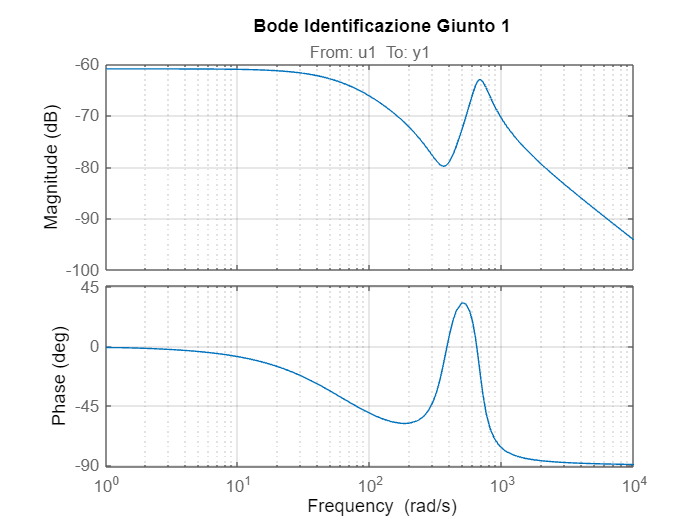

clear all
close all
clc
load ide_modelli_scara.mat

G1 = modello_continuo_q1;
figure
bode(G1)
grid on
title('Bode Identificazione Giunto 1')

tramite la funzione damp vediamo dove si trovano i poli e gli zeri del sistema identificato per trovare le frequenze di risonnza e antirisoanza per togliere il picco introdotto dalla risonanza

dataG1=damp(G1)

dataG1 =    68.5418
  671.4003
  671.4003


Di seguito viene progettato il filtro notch elimina banda con una frequenza vicina a 671 rad/s per rendere il diagramma più smooth

Poi per tentativi, sono stati decisi i valori ottimali di xci_z e xci_p che indicano la selettività del filtro notch

Wn_notch1 = 665;
xci_z1=0.15; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p1=0.7;
s=tf('s');
notch1=(s^2+2*xci_z1*Wn_notch1*s+Wn_notch1^2)/(s^2+2*xci_p1*Wn_notch1*s+Wn_notch1^2);

Verifica del filtro mediante l'utilizzo dei diagrammi di bode

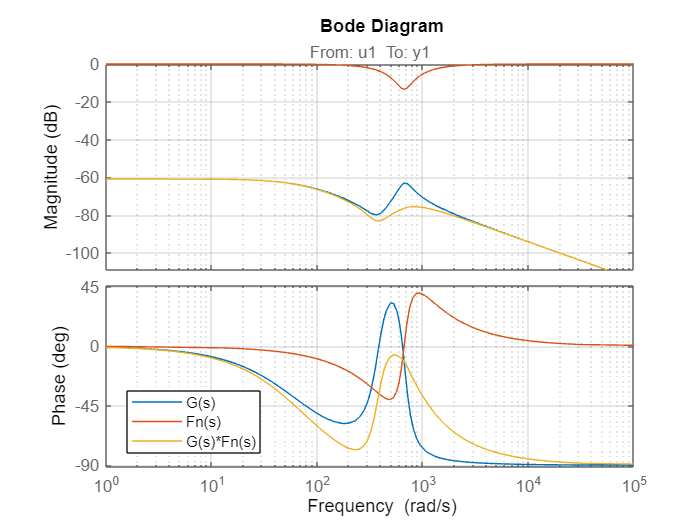

G1n = G1*notch1;
figure
bode(G1)
hold on
bode(notch1)
grid on
bode(G1n)
hold off
legend('G(s)','Fn(s)','G(s)*Fn(s)','Location','best')

Prima di procedere con la taratura si inserisce un filtro passa basso per attenuare le alte frequenze dell'azione di controllo 

Tf1_vel = (1/1000)

Tf1_vel = 1.0000e-03

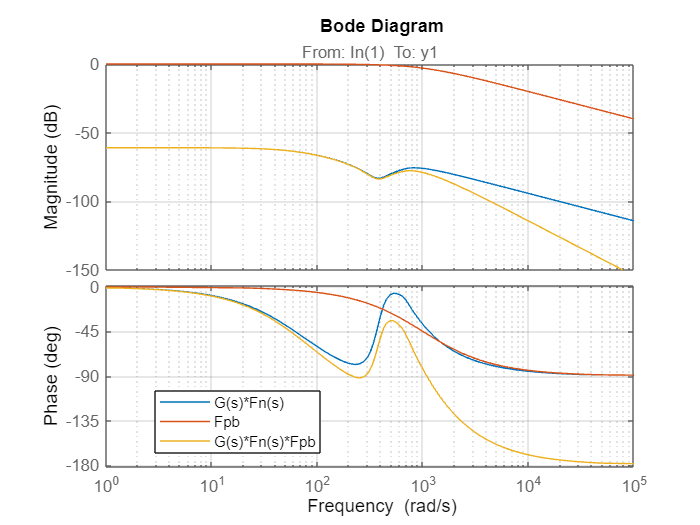

F = 1/(Tf1_vel*s+1);

figure
bode(G1n)
hold on 
bode(F)
bode(F*G1n)
legend('G(s)*Fn(s)','Fpb','G(s)*Fn(s)*Fpb','Location','best')
grid on
hold off

G1nf= G1n*F;

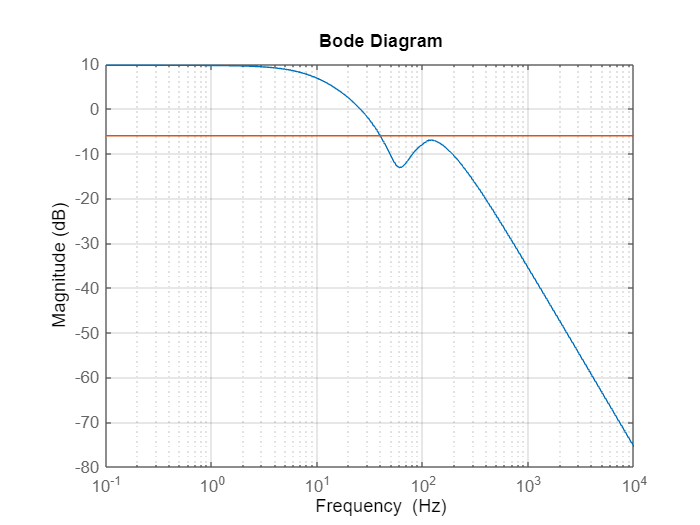


wc = 160;
Kp1_vel=1/abs(freqresp(G1nf,wc));

Cp1=Kp1_vel;

L1 = Cp1*G1nf;
h = bodeplot(L1);
setoptions(h,'FreqUnits','Hz','PhaseVisible','off','grid','on');
hold on 
bodeplot(tf(0.5))%valore corrispondente a  -6.0206dB

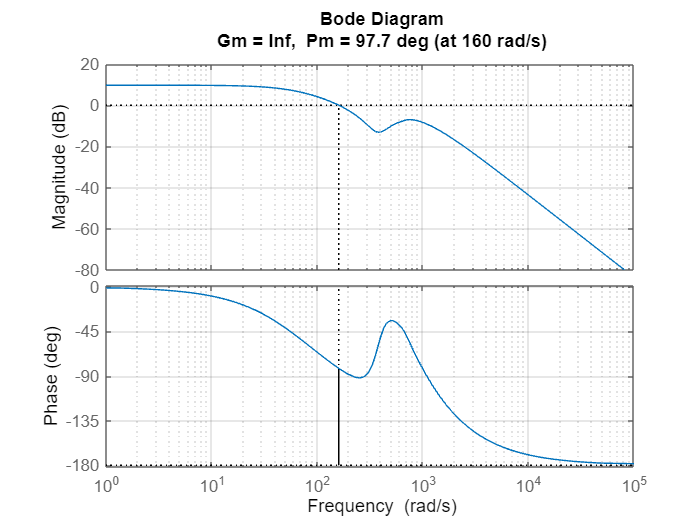



figure
title('Kp*Fn*F*G1')
margin(L1)
grid on

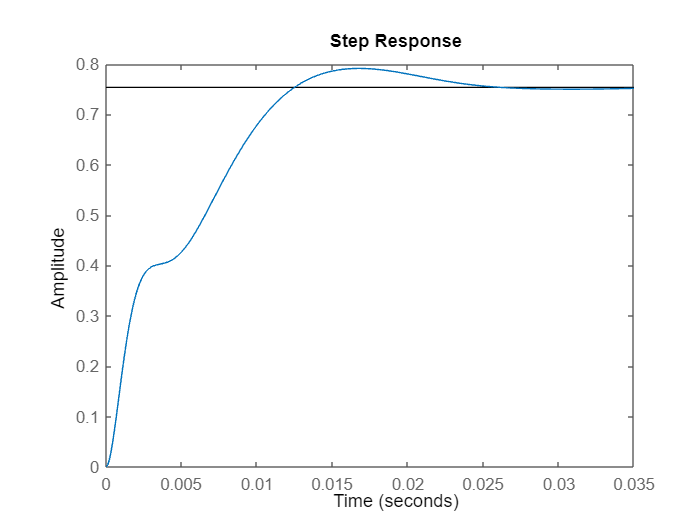


L1ret = feedback(L1,1);
%si esegue uno step del sistema in retroazione solo per sicurezza del
%procedimeneto fatto
figure
step(L1ret)

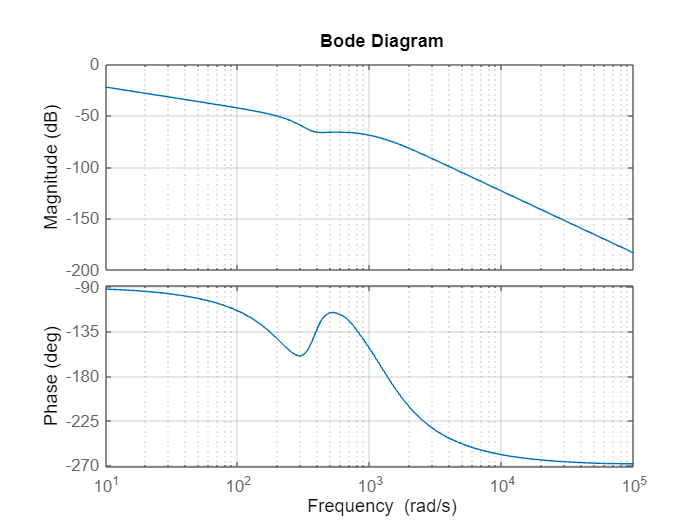

G1e = L1ret*1/s;
bode(G1e)
grid on

wc_des=150;
J=@(x)pivel_cost_function(x,G1e,wc_des);
MS=1.4;
wh=2000;
Fh_max=0.1;
wl=0.1;
Dh_max=0.1;%disturbo sul carico ridotto di almeno 10 volte
 
w_vector=logspace(-3,3)'; % [10^-3,10^3]
w_vector=sort([w_vector;wl;wh]);

nlcon=@(x)pivel_constraints(x,G1e,w_vector,MS,wh,Fh_max,wl,Dh_max);%anonious function

Risolvo il problema con fmincon, la soluzione è locale.

Impongo che $K_p\in[0.01,10000]$ e $K_i\in[0.01,10000]$

x0=[1,0.1];% scegliere un punto di partenza meglio provarne di diversi
x=fmincon(J,x0,[],[],[],[],[0.001 0.000001],[10000 10000],nlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =   144.6271    0.0106


Kp1_pos=x(1)

Kp1_pos = 144.6271

Ki1_pos=x(2)

Ki1_pos = 0.0106


C1pi=tf([Kp1_pos Ki1_pos],[1 0]);
figure
margin(C1pi*G1e)


step(feedback(C1pi*G1e,1))

%check della stabilità
C_fr=freqresp(C1pi*G1e,w_vector);
S_fr=1./(1+(C_fr)); % S = 1/(1+L) sensitivity function
max(abs(S_fr))

ans = 1.4000

Sezione di salvataggio dei parametri trovati nella fase di taratura

save("ctrl1.mat","Ki1_pos","Kp1_pos","Kp1_vel","Wn_notch1","xci_p1","xci_z1","Tf1_vel")